# **MATLAB Tutorial Solutions:**

**Q1: Symbolic vs. Numeric Variables**

This distinction is very important to how MATLAB performs calculations, so we need to be comfortable working with both kinds of variable. We will require both kinds depending on the question and context.

(a) Type *1/3* in the command window, and press enter. What is the output?

1/3

ans = 0.3333

This gives us a decimal approximation of 1/3, so 0.3333333333.

(b) Now, type *sym(1/3)* Do you see a different result?

sym(1/3)

$$ans = \frac{1}{3}$$

This has returned the *precise* value of 1/3 as a fraction.

(c) Lets's store some variables. Type *x = 1/3.* Is *x* numeric or symbolic?

x = 1/3

x = 0.3333

*x* has been assigned the numeric value of 1/3=0.3333333333, so it is numeric.

(d) Type *y = sym(1/3).* Is *y* numeric or symbolic?

y = sym(1/3)

$$y = \frac{1}{3}$$

This has assigned *y* to the symbolic interpretation of *1/3*, and so it is exactly *1/3.*

(e) We can obtain the value of a symbolic variable as a decimal approximation. Type *double(y)*

double(y)

ans = 0.3333

This asks for the value of *y*, but converts the output to a decimal approximation (i.e. it stated the value as a numeric variable). Note that *y* itself has not changed.

(f) Type *clear* What has this command done?

clear

This clears the workspace, so *x* and *y* have been forgotten.

(g) Store *2/3* in Matlab as a decimal approximation, stored as a variable called *z*

z = 2/3

z = 0.6667

(h) Obtain the value of *z *as a precise fraction.

sym(z)

$$ans = \frac{2}{3}$$

(i) Store *4/3* in Matlab as a precise fraction, stored as a variable called *w*

w=sym(4/3)

$$w = \frac{4}{3}$$

(j) Obtain the value of *w* as a decimal approximation and store it in a variable called *w2*

w2=double(w)

w2 = 1.3333

(k) We can declare a variable as symbolic without giving it a specific value. Try typing *syms p*

syms p

There is no specific output here, but note that *p* has appeared as a symbolic variable in the workspace, so now we could use it to differentiate a function of *p* for example.

**Q2: Calculations**

clear

(a)

15 + 39/2

ans = 34.5000

(b)

(15 + 39)/2

ans = 27

(c)

k = 6 * 104 - 2.^(-3)

k = 623.8750

(d)

cos(pi)

ans = -1

(e)

y = (exp(-3)+sqrt(19)).^(-2)

y = 0.0514

(f)

syms x
f = int(4*x+1,x)

$$f = x\,\left(2\,x+1\right)$$

(g)

syms x
int(sin(3*x),x,0,2*pi)

$$ans = 0$$

(h)

syms t
M = int(t*cos(2*t/pi),t,-5,3)

$$M = \frac{3\,\pi \,\sin\left(\frac{6}{\pi }\right)}{2}-\frac{5\,\pi \,\sin\left(\frac{10}{\pi }\right)}{2}+\frac{\pi^{2}\,\cos\left(\frac{6}{\pi }\right)}{4}-\frac{\pi^{2}\,\cos\left(\frac{10}{\pi }\right)}{4}$$

% to get an approximate answer:
double(M)

ans = 6.4146

(i)

syms x
y = int( (3*x^2+2*x-7)/(3+sin(2*x)) , x, -pi, pi )

$$y = \int_{-\pi }^{\pi }\frac{3\,x^{2}+2\,x-7}{\sin\left(2\,x\right)+3}\mathrm{d}x$$

double(y)

ans = 7.0809

**Q3: Graphs and curve plotting (Part I)**

clear

(a)

syms x

(b)

y1 = sin(x)

$$y1 = \sin\left(x\right)$$

y2 = sin(2*x+1)

$$y2 = \sin\left(2\,x+1\right)$$

(c)

fplot(x,y1)

(d)

hold on

(e)

fplot(x,y2)

(f)

xlim([2 6])

(g)

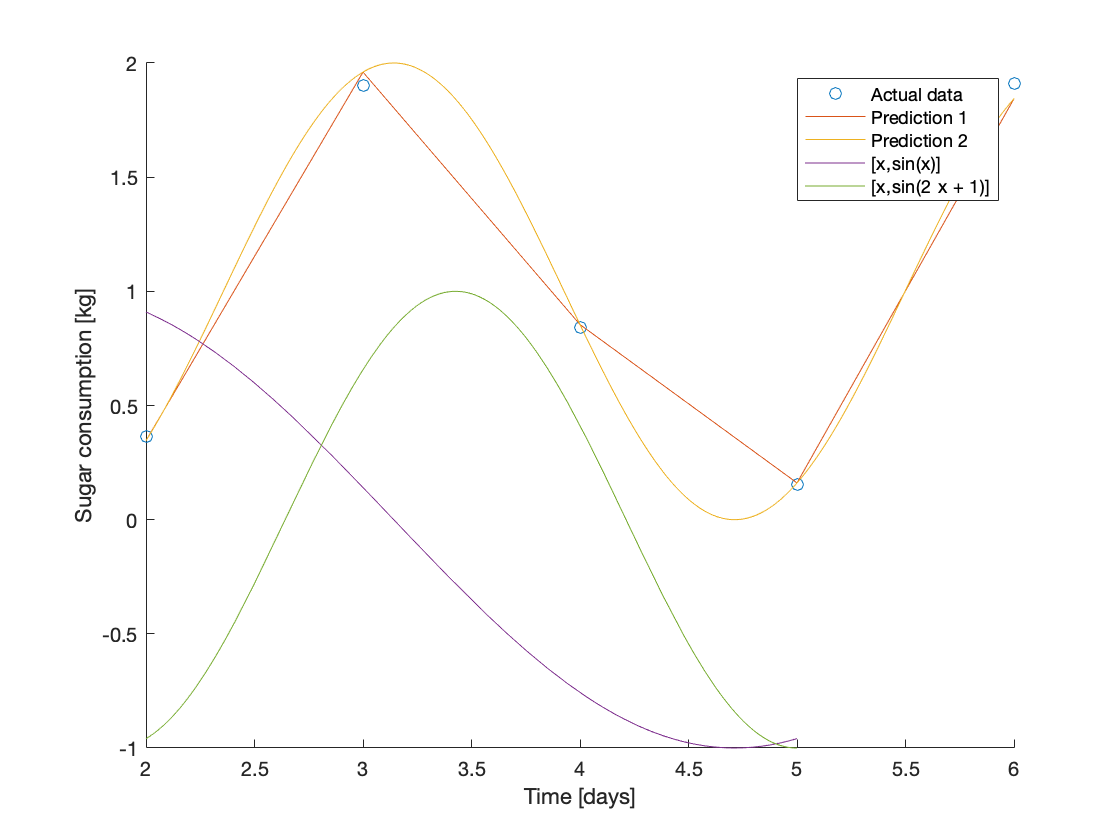

hold off

(h)

fplot(x,y1,[2 6])

(i)

hold on
fplot(x,y2,[2 6])

(j)

xlabel('x')
ylabel('y')

(k)

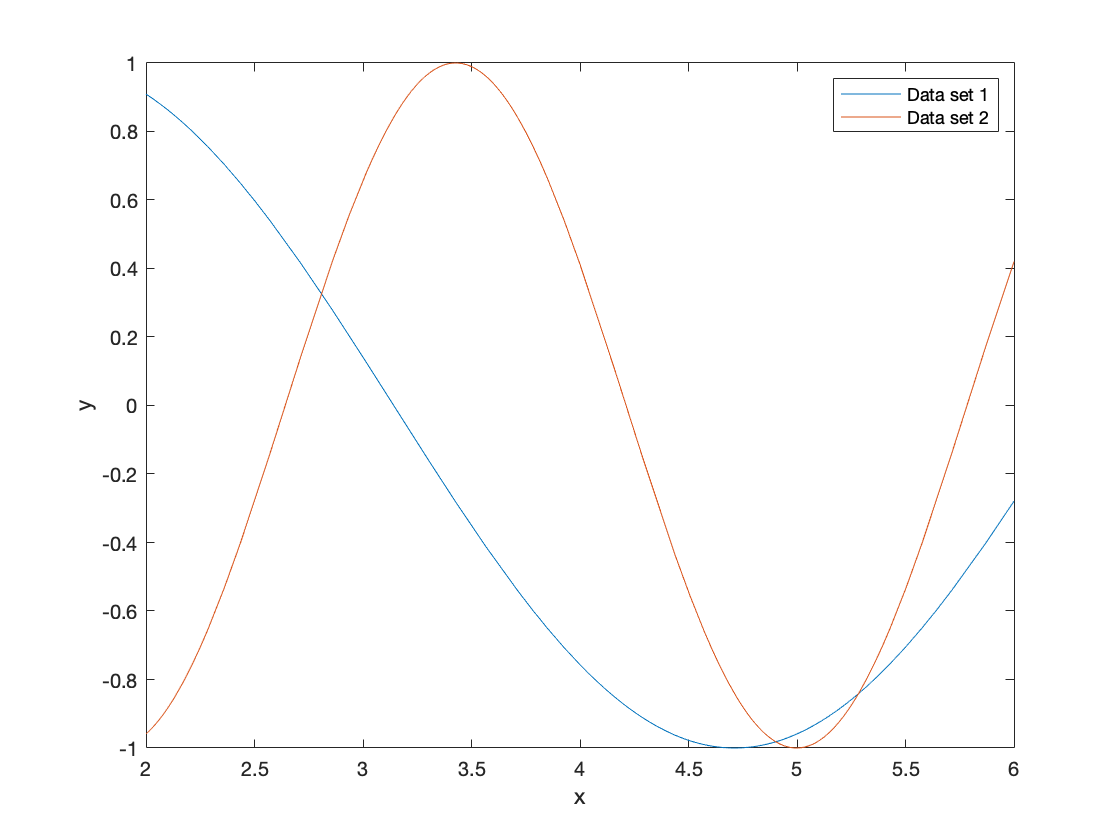

legend('Data set 1','Data set 2')

**Q4: Graphs and curve plotting (Part II)**

clear

(a)

t = [1 2 3 4 5 6 7 8 9 10]

t =      1     2     3     4     5     6     7     8     9    10


M = [0.573 0.366 1.900 0.841 0.155 1.910 1.187 0.040 1.703 1.411]

M =     0.5730    0.3660    1.9000    0.8410    0.1550    1.9100    1.1870    0.0400    1.7030    1.4110


(b) Including the semicolon ; means that the variable M will not be printed to the command window. This is especially useful if you are inputting very large data sets, and want to easily see the previous commands you've written without scrolling through many lines of data.

(c) We need to use "hold off" first, so that Matlab doesn't superimpose this scatter plot on our graph from Q2!

hold off

scatter(t,M)

(d)

Mpred = cos(2*t)+1

Mpred =     0.5839    0.3464    1.9602    0.8545    0.1609    1.8439    1.1367    0.0423    1.6603    1.4081


hold on
plot(t,Mpred)

(e)

t2 = linspace(1, 10, 1000)

t2 =     1.0000    1.0090    1.0180    1.0270    1.0360    1.0450    1.0541    1.0631    1.0721    1.0811    1.0901    1.0991    1.1081    1.1171    1.1261    1.1351    1.1441    1.1532    1.1622    1.1712    1.1802    1.1892    1.1982    1.2072    1.2162    1.2252    1.2342    1.2432    1.2523    1.2613    1.2703    1.2793    1.2883    1.2973    1.3063    1.3153    1.3243    1.3333    1.3423    1.3514    1.3604    1.3694    1.3784    1.3874    1.3964    1.4054    1.4144    1.4234    1.4324    1.4414


Mpred2 = cos(2*t2)+1

Mpred2 =     0.5839    0.5675    0.5514    0.5353    0.5195    0.5037    0.4882    0.4728    0.4576    0.4425    0.4276    0.4130    0.3985    0.3842    0.3701    0.3562    0.3425    0.3290    0.3158    0.3028    0.2900    0.2774    0.2650    0.2529    0.2411    0.2295    0.2181    0.2070    0.1962    0.1856    0.1753    0.1652    0.1554    0.1459    0.1367    0.1277    0.1191    0.1107    0.1026    0.0948    0.0873    0.0801    0.0731    0.0665    0.0602    0.0542    0.0485    0.0431    0.0380    0.0333


plot(t2, Mpred2)

(f)

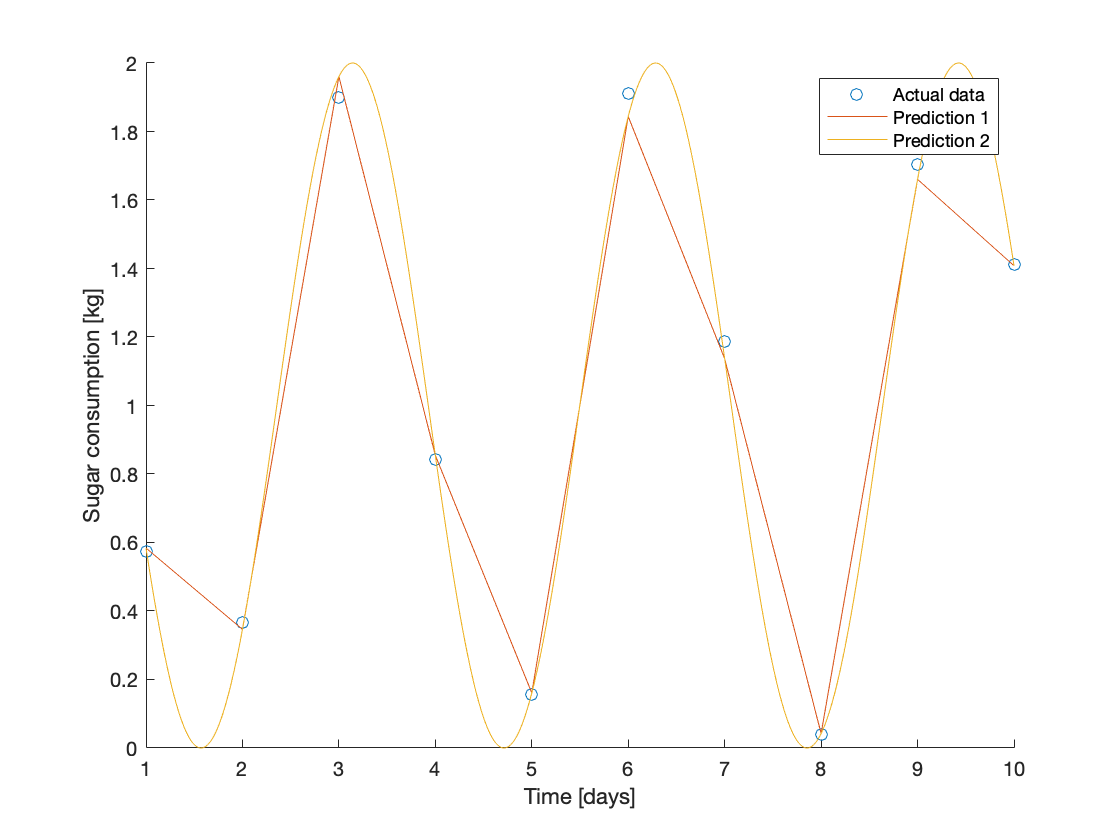

legend('Actual data','Prediction 1','Prediction 2')
xlabel('Time [days]')
ylabel('Sugar consumption [kg]')